## ESD2: Laboratory 1

Parameters:

b = 60; % baseline [mm]
f = 7; % focal length [mm]
ps = .006; % focal length [mm]
xNumPix = 752; % total number of pixels in x direction of the sensor [px]
yNumPix = 480; % total number of pixels in y direction of the sensor [px]
cxLeft = xNumPix/2; % left camera x center [px]
cxRight = xNumPix/2; % right camera x center [px]

% extra param
cyLeft = yNumPix/2;
cyRight = yNumPix/2;

xLeft = 396; % What does this represent?
xRight = 356; % What does this represent?

Depth equation with a single shift:

d = (abs((xLeft-cxLeft)-(xRight-cxRight))*ps); % disparity [mm]
Z = (b * f)/(d * 1000); % depth [m]
disp(['The depth is: ' num2str(Z) ' [m]'])

The depth is: 1.75 [m]


Depth equation with shifts:

shift = 0:350;
xLeft = cxLeft + shift;
xRight = cxRight - shift;
d = (abs((xLeft-cxLeft)-(xRight-cxRight))*ps); % disparity [mm]
Z = (b * f)./(d * 1000); % depth [m]
disp(['The depth is: ' num2str(Z) ' [m]'])

The depth is: Inf            35          17.5      11.66667          8.75             7      5.833333             5         4.375      3.888889           3.5      3.181818      2.916667      2.692308           2.5      2.333333        2.1875      2.058824      1.944444      1.842105          1.75      1.666667      1.590909      1.521739      1.458333           1.4      1.346154      1.296296          1.25      1.206897      1.166667      1.129032       1.09375      1.060606      1.029412             1     0.9722222     0.9459459     0.9210526     0.8974359         0.875     0.8536585     0.8333333     0.8139535     0.7954545     0.7777778     0.7608696     0.7446809     0.7291667     0.7142857           0.7     0.6862745     0.6730769     0.6603774     0.6481481     0.6363636         0.625     0.6140351     0.6034483     0.5932203     0.5833333     0.5737705     0.5645161     0.5555556      0.546875     0.5384615      0.530303     0.5223881     0.5147059     0.5072464           0.5   

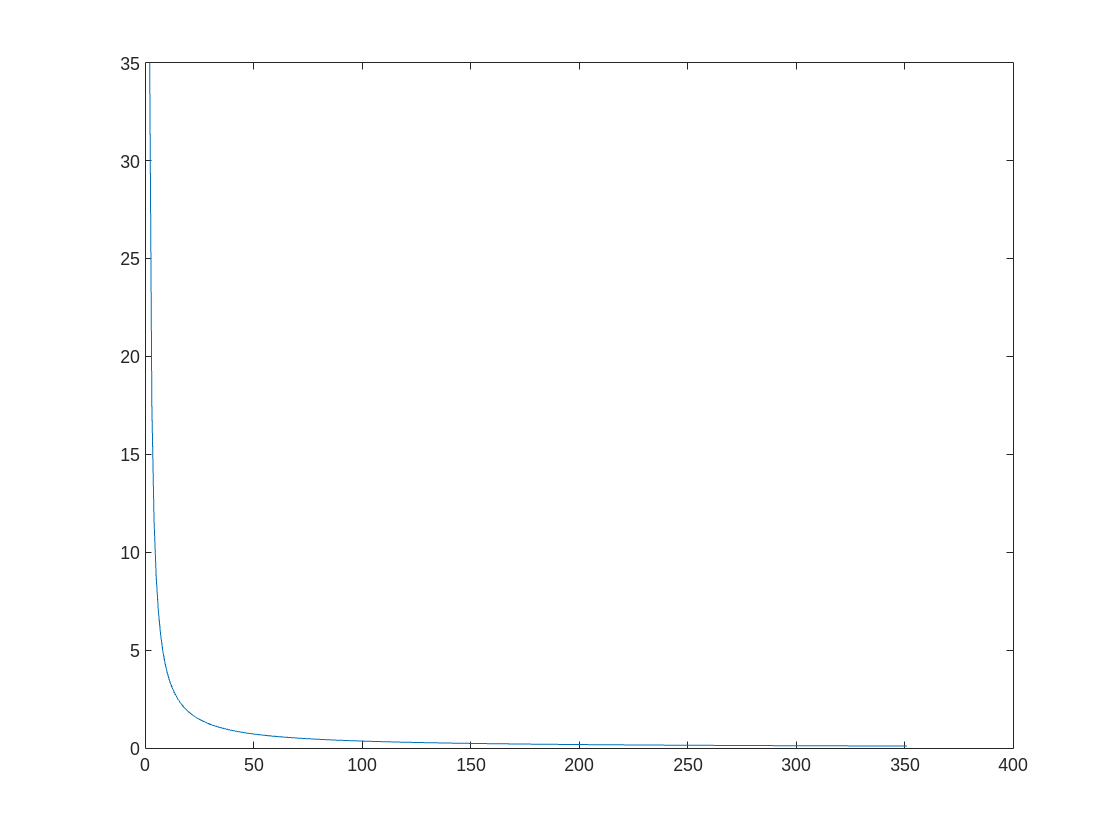

plot(Z)

Plot Depth with shifts vs Disparity:

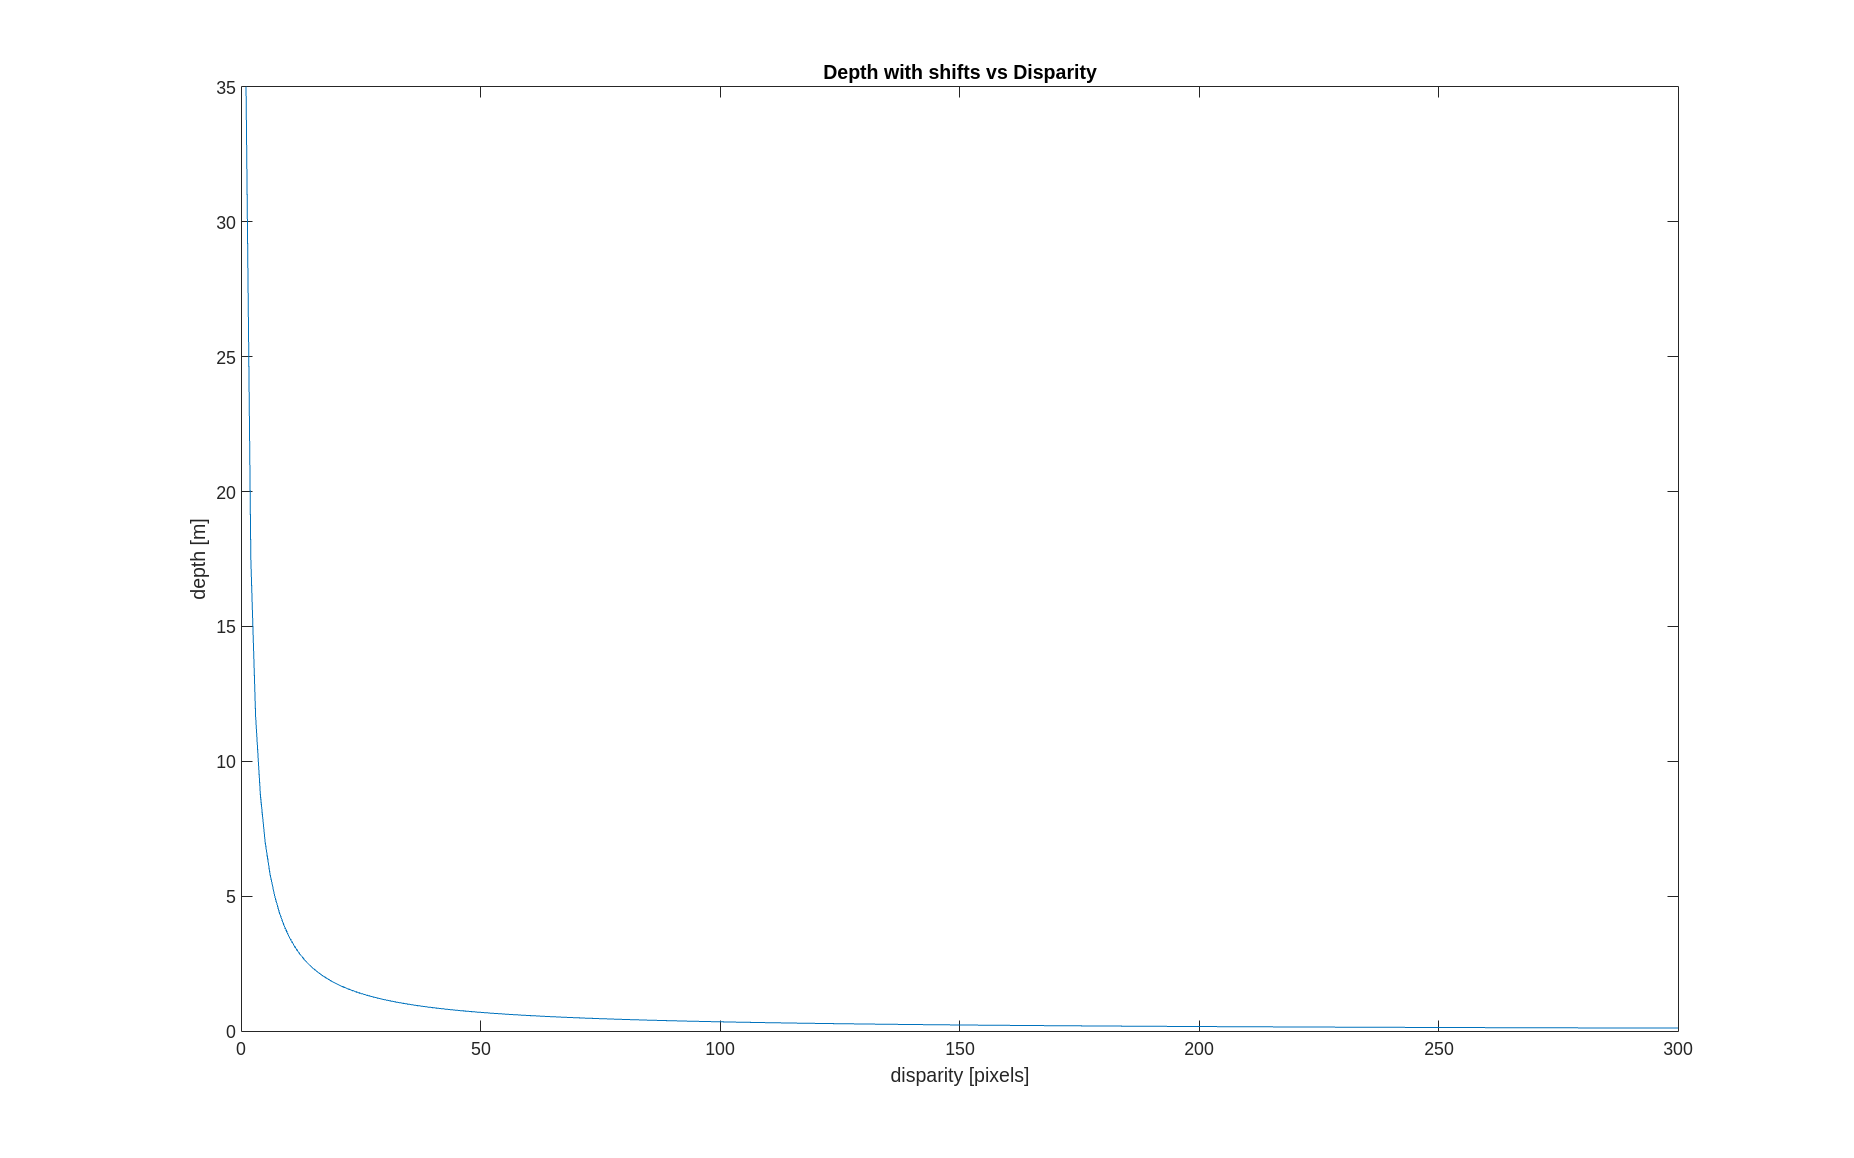

Fig = figure('Position', get(0,"ScreenSize"));
plot(shift,Z);
xlabel("disparity [pixels]");
ylabel("depth [m]");
xlim([0 300]);
title("Depth with shifts vs Disparity");
saveas(Fig, append('depth_vs_disparity.png'));

Subplots

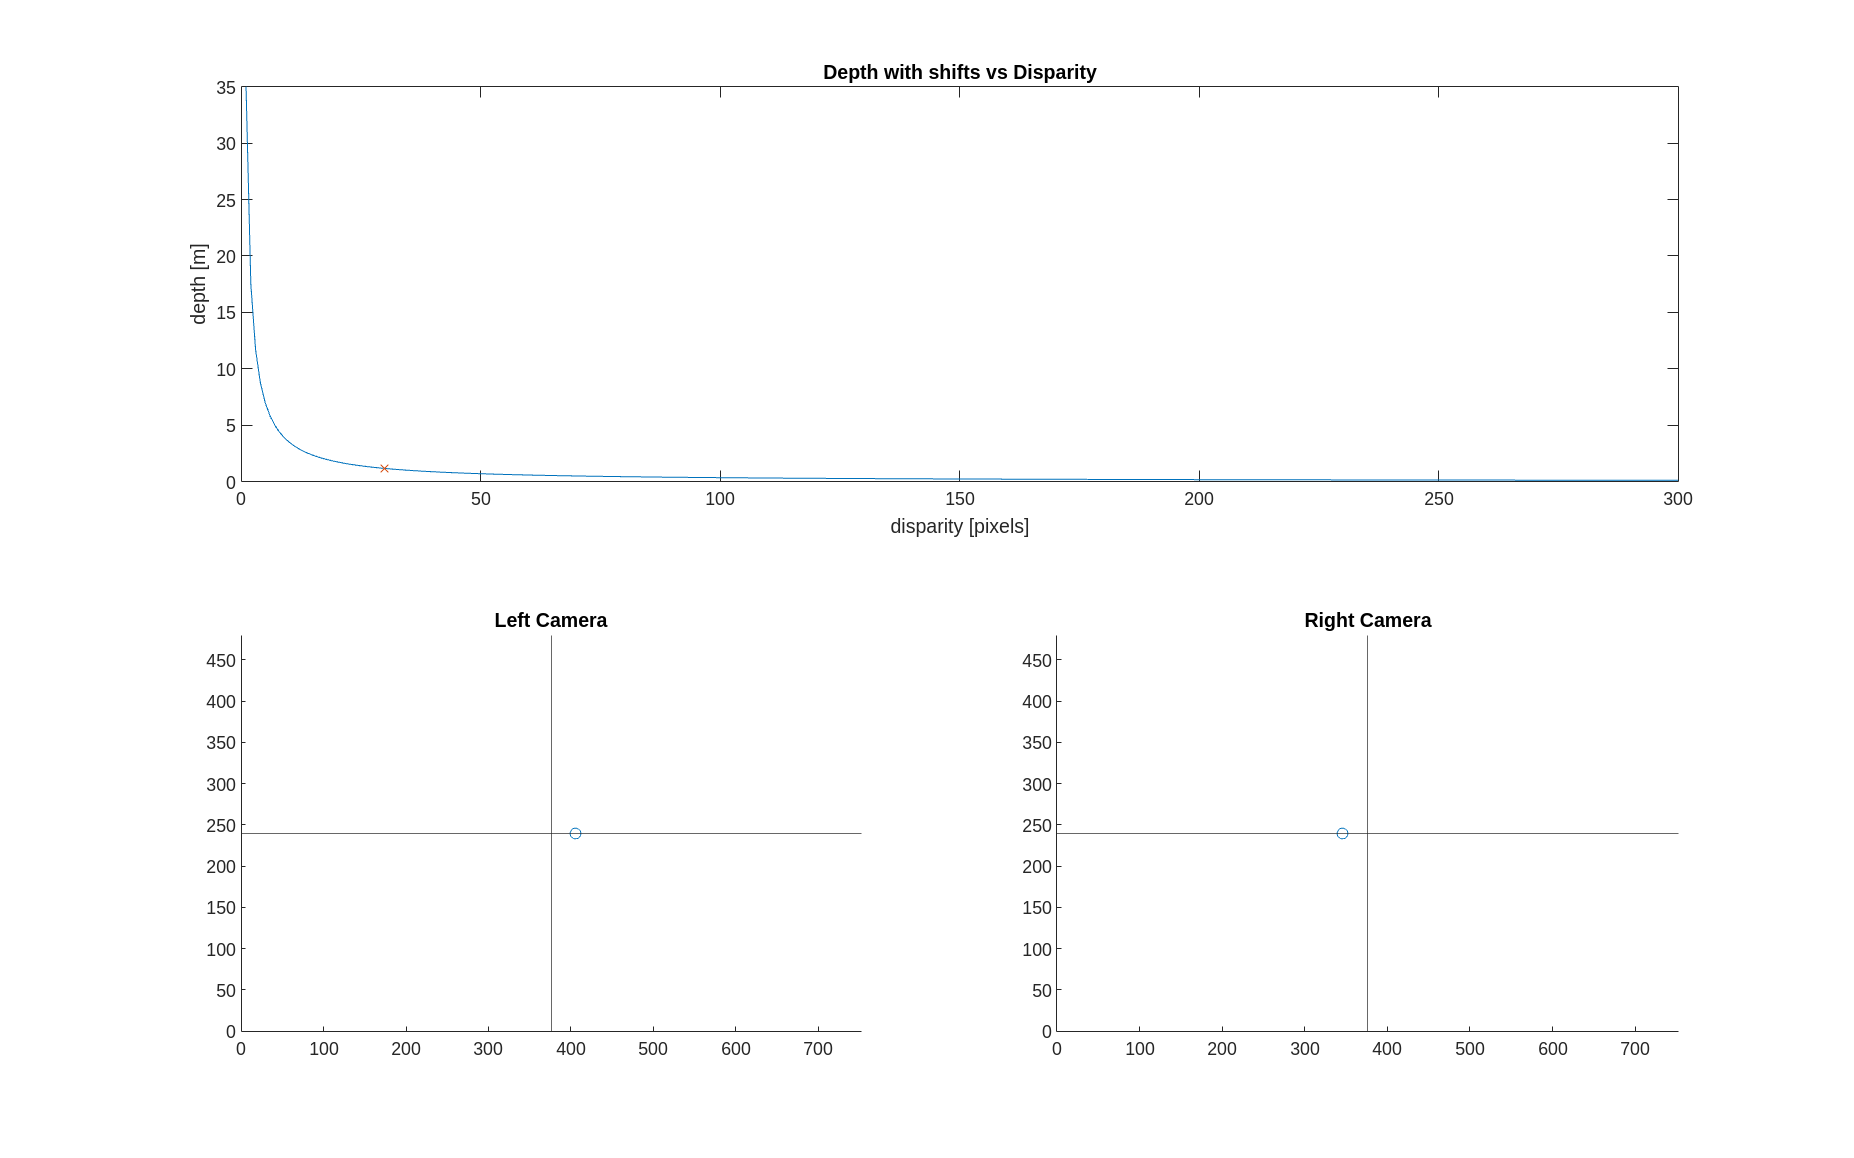

Fig = figure('Position', get(0,"ScreenSize"));
subplot(2,2,[1,2]);
plot(shift,Z);

shift = 30; % fixed pixel shift
xLeft = cxLeft + shift;
xRight = cxRight - shift;
d = (abs((xLeft-cxLeft)-(xRight-cxRight))*ps); % disparity [mm]
Z = (b * f)./(d * 1000); % depth [m]

hold on
plot(shift, Z, 'x')
xlabel("disparity [pixels]");
ylabel("depth [m]");
xlim([0 300]);
title("Depth with shifts vs Disparity");

subplot (2,2,3)
scatter(xLeft, cyLeft)
hold on
xline(cxLeft)
yline(cyLeft)
xlim([0 xNumPix])
ylim([0 yNumPix])
title('Left Camera')

subplot (2,2,4)
scatter(xRight, cyRight)
hold on
xline(cxRight)
yline(cyRight)
xlim([0 xNumPix])
ylim([0 yNumPix])
title('Right Camera')

saveas(Fig, append('depth_vs_disparity_subplots.png'));